# Visualizing the Bungee Jump

This code defines the equations and assumptions from the previous section.

syms y(t) b k
m = 75

m = 75

assume(y(t),'real')
assume([b k],'positive')
bungeeEqn = m*diff(y,t,2) + b*diff(y,t) + k*y == 0

$$bungeeEqn(t) = 75\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+b\,\frac{\partial }{\partial t}y\left(t\right)+k\,y\left(t\right)=0$$

ic = y(0) == 75

$$ic = y\left(0\right)=75$$

dy(t) = diff(y,t)

$$dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

ic2 = dy(0) == 0

$$ic2 = \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=0$$

## Task 1

The initial position of the bungee jumper is stored in `ic` and the initial velocity is stored in `ic2`.

The `dsolve` function can solve a differential equation with multiple initial conditions.

`sol` `=` `dsolve``(``diffEqn``,` `[``cond1` `cond2` `cond3` `...``])`

Task

Use `dsolve` to solve the differential equation `bungeeEqn` with conditions `ic` and `ic2`. Store the result in `ysol`.

ysol=dsolve(bungeeEqn,[ic ic2])

$$ysol = \begin{array}{l} \frac{75\,{\mathrm{e}}^{-t\,\left(\frac{b}{150}-\frac{\sigma_{1}}{150}\right)}\,\left(b+\sigma_{1}\right)}{2\,\sigma_{1}}-\frac{75\,{\mathrm{e}}^{-t\,\left(\frac{b}{150}+\frac{\sigma_{1}}{150}\right)}\,\left(b-\sigma_{1}\right)}{2\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{b^{2}-300\,k} \end{array}$$

## Task 2

The solution depends on the parameters *b* and *k*. In order to plot the solution, you will need to substitute values for these parameters.

Task

Substitute 4 for `b` and 8 for `k` in  `ysol`, and store the result as `yequil`. Plot `yequil` for *t* from 0 to 150.

yequil=subs(ysol,[b k],[4 8])

$$yequil = -\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{t\,\left(-\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150}\right)}\,\left(4+\sqrt{2384}\,\mathrm{i}\right)\,\mathrm{i}}{4768}-\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{-t\,\left(\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150}\right)}\,\left(-4+\sqrt{2384}\,\mathrm{i}\right)\,\mathrm{i}}{4768}$$

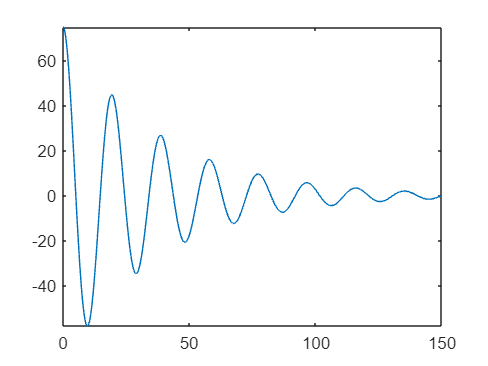

fplot(yequil,[0 150])

## Task 3

The plot shows the position of the bungee jumper  relative to equilibrium. To instead plot the height of the bungee jumper relative to the ground, you can apply a shift to the function. 

The bungee cord's equilibrium length is 75 meters, and the height of the  bridge is 152 meters. So the bungee jumper is 77 meters off the ground  at equilibrium.

Task

Find the height of the bungee jumper by adding 77 to `yequil`. Plot the height for *t* from 0 to 150.

yeq77=yequil+77

$$yeq77 = 77-\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{t\,\left(-\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150}\right)}\,\left(4+\sqrt{2384}\,\mathrm{i}\right)\,\mathrm{i}}{4768}-\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{-t\,\left(\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150}\right)}\,\left(-4+\sqrt{2384}\,\mathrm{i}\right)\,\mathrm{i}}{4768}$$

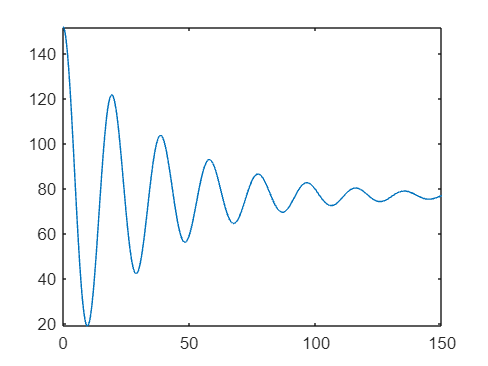

fplot(yeq77,[0 150])

## Further Practice

You've modeled a bungee jump as a mass-spring-damper system, and plotted the height of the bungee jumper over time. 

How could you find the total distance traveled by the bungee jumper? The total distance traveled is the length of the curve `yequil`. 

The formula for the length of a curve z(t) from t=a to t=b isL=∫ba√1+(dzdt)2dt

To find the total distance traveled by the bungee jumper in the first 100 seconds of the jump, use `int` to calculate the integral from 0 to 100.

`d` `=` `sqrt``(``1``+``(``diff``(``yequil``,``t``))``^``2``)`

`L` `=` `int``(``d``,``0``,``100``)`

Use `double` to convert the result to a numeric value.

`double``(``L``)`

d = sqrt(1+(diff(yequil,t))^2)

$$d = \begin{array}{l} \sqrt{{\left(\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{t\,\sigma_{1}}\,\left(4+\sqrt{2384}\,\mathrm{i}\right)\,\sigma_{1}\,\mathrm{i}}{4768}-\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{-t\,\sigma_{2}}\,\left(-4+\sqrt{2384}\,\mathrm{i}\right)\,\sigma_{2}\,\mathrm{i}}{4768}\right)}^{2}+1}\\ \mathrm{where}\\ \sigma_{1}=-\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150}\\ \sigma_{2}=\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150} \end{array}$$

L = int(d,0,100)

$$L = \begin{array}{l} \int_{0}^{100}\sqrt{{\left(\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{t\,\sigma_{1}}\,\left(4+\sqrt{2384}\,\mathrm{i}\right)\,\sigma_{1}\,\mathrm{i}}{4768}-\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{-t\,\sigma_{2}}\,\left(-4+\sqrt{2384}\,\mathrm{i}\right)\,\sigma_{2}\,\mathrm{i}}{4768}\right)}^{2}+1}\mathrm{d}t\\ \mathrm{where}\\ \sigma_{1}=-\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150}\\ \sigma_{2}=\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150} \end{array}$$

double(L)

ans = 565.5103